ЛАБОРАТОРНА РОБОТА №4

з навчальної дисципліни «Математичне моделювання систем і процесів»

Виконав:

Студент 5 курсу

Групи ФФ-21мн

Бондар О.В.

Перевірив:

Гордійко Н.О.

Варіант №1 

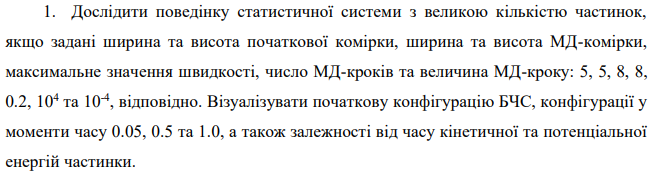

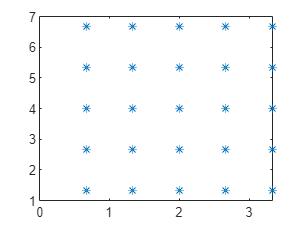

clearvars;
Nx=5;
Ny=5;
Lx=8;
Ly=8;

Vmax=0.2;
dt=10^(-4);
Ni=10^4;


N=Nx*Ny;

Posrow=Ly/(Ny+1); Poscol=Lx/(Nx+1);
i=1;
for Rows=1:Ny
    for Col=1:Nx
        x(i)=Poscol*Col/2; 
        y(i)=Posrow*Rows; 
        Vx(i)=Vmax*(2*rand(1)-1); 
        Vy(i)=Vmax*(2*rand(1)-1);
        i=i+1;
    end
end
plot(x,y, '*')


T=0;
T1=0.05;
T2=0.5;
T3=1.0;


RV=init(Lx,Ly,Nx,Ny,Vmax,T) 

RV =     0.6667    1.3333    0.0734   -0.0682
    1.3333    1.3333    0.2198   -0.1206
    2.0000    1.3333    0.0819    0.0317
    2.6667    1.3333   -0.0241   -0.1534
    3.3333    1.3333   -0.1690   -0.0418
    0.6667    2.6667   -0.1054    0.0801
    1.3333    2.6667   -0.0309    0.1264
    2.0000    2.6667    0.1146    0.0182
    2.6667    2.6667   -0.1083    0.1727
    3.3333    2.6667   -0.0729    0.1596


accfunc=Acc(RV,Lx,Ly,N)

accfunc = 1.0e+03 *

   -6.1681    0.0023         0
    0.0017    0.0031         0
   -0.0000    0.0032         0
   -0.0017    0.0031         0
    6.1681    0.0023         0
   -6.1676    0.0000         0
    0.0019    0.0001         0
   -0.0000    0.0001         0
   -0.0019    0.0001         0
    6.1676    0.0000         0


z1=Fx(x,y)

z1 =    -0.3706   -0.1322   -0.0294   -0.0071   -0.0020   -0.0034   -0.0035   -0.0022   -0.0011   -0.0005   -0.0002   -0.0002   -0.0002   -0.0002   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000


z2=Fy(x,y)

z2 =    -0.7413   -0.1322   -0.0196   -0.0035   -0.0008   -0.0135   -0.0071   -0.0029   -0.0011   -0.0004   -0.0009   -0.0007   -0.0004   -0.0002   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000


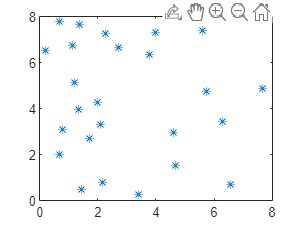

md = md(:,:,1) =

   1.0e+03 *

    0.0007    0.0013    0.0001   -0.0001   -6.1681    0.0023         0
    0.0013    0.0013    0.0002   -0.0001    0.0017    0.0031         0
    0.0020    0.0013    0.0001    0.0000   -0.0000    0.0032         0
    0.0027    0.0013   -0.0000   -0.0002   -0.0017    0.0031         0
    0.0033    0.0013   -0.0002   -0.0000    6.1681    0.0023         0
    0.0007    0.0027   -0.0001    0.0001   -6.1676    0.0000         0
    0.0013    0.0027   -0.0000    0.0001    0.0019    0.0001         0
    0.0020    0.0027    0.0001    0.0000   -0.0000    0.0001         0
    0.0027    0.0027   -0.0001    0.0002   -0.0019    0.0001         0
    0.0033    0.0027   -0.0001    0.0002    6.1676    0.0000         0
    0.0007    0.0040   -0.0001   -0.0001   -6.1676    0.0000         0
    0.0013    0.0040   -0.0001    0.0000    0.0019    0.0000         0
    0.0020    0.0040   -0.0001   -0.0002   -0.0000    0.0000         0
    0.0027    0.0040    0.0001   -0.0001   -0


% verletfunc=Verlet(RV,Lx,Ly,N,dt)

md=MD(Lx,Ly,N,Ni,dt,RV)




RV1=init(Lx,Ly,Nx,Ny,Vmax,T1) 

RV1 =     0.6764    1.3247    0.1773   -0.1892
    1.3421    1.3237    0.1574   -0.2087
    2.0037    1.3390    0.0552    0.0976
    2.6673    1.3410   -0.0047    0.1382
    3.3413    1.3359    0.1413    0.0344
    0.6594    2.6610   -0.1632   -0.1288
    1.3270    2.6575   -0.1455   -0.1992
    1.9921    2.6690   -0.1755    0.0306
    2.6755    2.6638    0.1575   -0.0741
    3.3315    2.6764   -0.0541    0.1778


accfunc1=Acc(RV1,Lx,Ly,N)

accfunc1 = 1.0e+03 *

   -6.2916    0.0116         0
   -0.5122   -0.1637         0
    0.2579    0.1407         0
    1.2108    0.0642         0
    5.3350   -0.0388         0
   -6.0586    0.0320         0
   -0.2814   -0.1417         0
    1.9021    0.1438         0
   -3.1681   -0.1802         0
    7.6060    0.1462         0


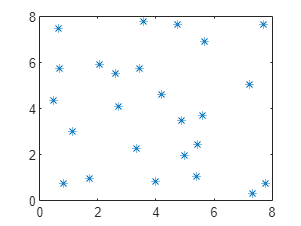

md1 = md1(:,:,1) =

   1.0e+03 *

    0.0007    0.0013    0.0002   -0.0002   -6.2916    0.0116         0
    0.0013    0.0013    0.0002   -0.0002   -0.5122   -0.1637         0
    0.0020    0.0013    0.0001    0.0001    0.2579    0.1407         0
    0.0027    0.0013   -0.0000    0.0001    1.2108    0.0642         0
    0.0033    0.0013    0.0001    0.0000    5.3350   -0.0388         0
    0.0007    0.0027   -0.0002   -0.0001   -6.0586    0.0320         0
    0.0013    0.0027   -0.0001   -0.0002   -0.2814   -0.1417         0
    0.0020    0.0027   -0.0002    0.0000    1.9021    0.1438         0
    0.0027    0.0027    0.0002   -0.0001   -3.1681   -0.1802         0
    0.0033    0.0027   -0.0001    0.0002    7.6060    0.1462         0
    0.0007    0.0040    0.0002    0.0001   -6.0632   -0.0163         0
    0.0013    0.0040    0.0002    0.0001   -1.9480    0.0421         0
    0.0020    0.0040   -0.0001    0.0000    1.6192    0.0451         0
    0.0027    0.0040   -0.0001   -0.0001   

md1=MD(Lx,Ly,N,Ni,dt,RV1)


RV2=init(Lx,Ly,Nx,Ny,Vmax,T1) 

RV2 =     0.6723    1.3372    0.1337    0.0624
    1.3235    1.3402   -0.1755    0.1222
    2.0084    1.3388    0.1895    0.0933
    2.6575    1.3309   -0.1624   -0.0638
    3.3374    1.3379    0.1023    0.0767
    0.6612    2.6620   -0.0897   -0.1075
    1.3368    2.6662    0.0898   -0.0241
    2.0025    2.6614    0.0701   -0.1205
    2.6602    2.6733   -0.1086    0.1167
    3.3387    2.6754    0.1273    0.1587


accfunc2=Acc(RV2,Lx,Ly,N)

accfunc2 = 1.0e+03 *

   -8.4182   -0.0363         0
    4.1140    0.0509         0
   -4.4779    0.1005         0
    4.0364   -0.1524         0
    4.7457    0.0514         0
   -5.1617   -0.0319         0
   -1.1241    0.0774         0
   -1.0716   -0.1784         0
    2.4732    0.1178         0
    4.8842    0.0152         0


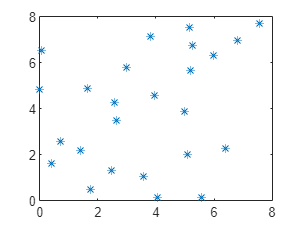

md2 = md2(:,:,1) =

   1.0e+03 *

    0.0007    0.0013    0.0001    0.0001   -8.4182   -0.0363         0
    0.0013    0.0013   -0.0002    0.0001    4.1140    0.0509         0
    0.0020    0.0013    0.0002    0.0001   -4.4779    0.1005         0
    0.0027    0.0013   -0.0002   -0.0001    4.0364   -0.1524         0
    0.0033    0.0013    0.0001    0.0001    4.7457    0.0514         0
    0.0007    0.0027   -0.0001   -0.0001   -5.1617   -0.0319         0
    0.0013    0.0027    0.0001   -0.0000   -1.1241    0.0774         0
    0.0020    0.0027    0.0001   -0.0001   -1.0716   -0.1784         0
    0.0027    0.0027   -0.0001    0.0001    2.4732    0.1178         0
    0.0033    0.0027    0.0001    0.0002    4.8842    0.0152         0
    0.0007    0.0040   -0.0001   -0.0001   -6.1855   -0.0571         0
    0.0013    0.0040   -0.0001   -0.0000    0.2528   -0.0150         0
    0.0020    0.0040   -0.0001    0.0001   -0.4392    0.2356         0
    0.0027    0.0040   -0.0001   -0.0002   

md2=MD(Lx,Ly,N,Ni,dt,RV2)


RV3=init(Lx,Ly,Nx,Ny,Vmax,T1) 

RV3 =     0.6709    1.3357    0.0794    0.0129
    1.3302    1.3421   -0.0687    0.1399
    1.9925    1.3379   -0.1561    0.0578
    2.6696    1.3400    0.0526    0.0988
    3.3313    1.3383   -0.0467    0.0655
    0.6734    2.6631    0.1281   -0.1055
    1.3344    2.6762    0.0149    0.1572
    2.0010    2.6633    0.0137   -0.1023
    2.6691    2.6639    0.0418   -0.0902
    3.3385    2.6649    0.0966   -0.0689


accfunc3=Acc(RV3,Lx,Ly,N)

accfunc3 = 1.0e+03 *

   -7.1490   -0.0666         0
    0.4217    0.1138         0
    1.7118   -0.0538         0
   -1.7956    0.0355         0
    6.8111   -0.0148         0
   -6.8871   -0.1370         0
    0.7308    0.2569         0
    0.1605   -0.1254         0
    0.1555   -0.0039         0
    5.8403    0.0093         0


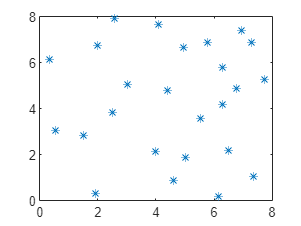

md3 = md3(:,:,1) =

   1.0e+03 *

    0.0007    0.0013    0.0001    0.0000   -7.1490   -0.0666         0
    0.0013    0.0013   -0.0001    0.0001    0.4217    0.1138         0
    0.0020    0.0013   -0.0002    0.0001    1.7118   -0.0538         0
    0.0027    0.0013    0.0001    0.0001   -1.7956    0.0355         0
    0.0033    0.0013   -0.0000    0.0001    6.8111   -0.0148         0
    0.0007    0.0027    0.0001   -0.0001   -6.8871   -0.1370         0
    0.0013    0.0027    0.0000    0.0002    0.7308    0.2569         0
    0.0020    0.0027    0.0000   -0.0001    0.1605   -0.1254         0
    0.0027    0.0027    0.0000   -0.0001    0.1555   -0.0039         0
    0.0033    0.0027    0.0001   -0.0001    5.8403    0.0093         0
    0.0007    0.0040   -0.0000    0.0000   -5.0949    0.0554         0
    0.0013    0.0040    0.0002   -0.0001   -1.4050   -0.1360         0
    0.0020    0.0040    0.0001    0.0001    0.6320    0.2048         0
    0.0027    0.0040    0.0002   -0.0002   

md3=MD(Lx,Ly,N,Ni,dt,RV3)





% розрахунок енергій
Ep=0;
for i=1:N-1
    for j=i+1:N
        Dx=x(i)-x(j);
        if abs(Dx)>Lx/2
            Dx=Dx-sign(Dx)*Lx;
        end
        Dy=y(i)-y(j);
        if abs(Dy)>Ly/2
            Dy=Dy-sign(Dy)*Ly;
        end
        r=(Dx^2+Dy^2).^0.5; Ep=Ep+4*(1/r.^12-1/r.^6);
    end
end
Ek=0;
for i=1:N
    Ek=Ek+0.5*(Vx(i)^2+Vy(i)^2);
end
Ep

Ep = 9.4335e+03

Ek

Ek = 0.3198

Esum = Ep+Ek 

Esum = 9.4338e+03